# Evaluating Object Detection Model

## Prepare the test data

% Load the detector and the ground truth for the test images
load trainedYOLOXDetector.mat evYoloDetector
load parkingTestGT.mat parkingTestGT

% Create a combined datastore of the images and bounding box data
[imds, blds] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imds, blds);

## **Run the detector on the test images**

testResults = detect(evYoloDetector, testData, "Threshold", 0.5)

testResults = 100×3 table
                    Boxes                        Scores            Labels      
    ______________________________________    ____________    _________________

    {[200.9917 109.6216 74.2302 106.3006]}    {[  0.9328]}    {[EV           ]}
    {[126.6339 34.0009 206.0933 254.5811]}    {[  0.7431]}    {[EV           ]}
    {[ 200.9282 83.1092 84.1342 161.7612]}    {[  0.9255]}    {[Charger      ]}
    {[180.9712 95.5024 116.5943 129.7557]}    {[  0.8661]}    {[EV           ]}
    {[149.6494 47.9200 199.1789 224.6101]}    {[  0.8721]}    {[EV           ]}
    {[ 330.3845 58.1651 93.0993 104.1917]}    {[  0.8986]}    {[EV           ]}
    {[ 230.9915 127.7039 75.2847 70.4420]}    {[  0.9037]}    {[Accessible   ]}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {0×4 single                          }    {0×1 single}    {0×1 cate

### Out of memory errors

% testResults = detect(evYoloDetector, testData, "Threshold", 0.5, "MiniBatchSize", 50)

## Visualize detections

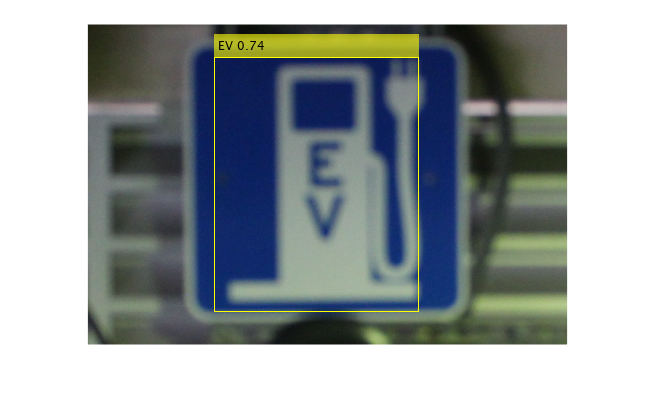

numImages = height(testResults);  % To set a limit on the control
imgIdx = 2;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

## Evaluate detection results

% Set the IoU threshold
iou = [0.5 0.75];

% Evaluate the detector
metrics = evaluateObjectDetection(testResults, testData, iou);

classNames = metrics.ClassNames

classNames = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


[datasetSummary, classSummary] = summarize(metrics)

datasetSummary = 1×4 table
    NumObjects    mAPOverlapAvg    mAP0.5     mAP0.75
    __________    _____________    _______    _______

       135           0.72296       0.82783    0.61809


classSummary = 3×4 table
                  NumObjects    APOverlapAvg     AP0.5     AP0.75 
                  __________    ____________    _______    _______

    Accessible        48          0.54829       0.60417    0.49242
    Charger           29          0.67489       0.89655    0.45324
    EV                58          0.94569       0.98276    0.90861


## Visualize precision-recall curves for different classes

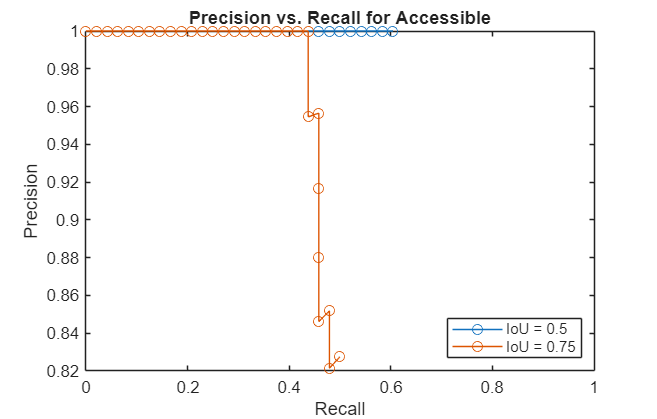

[precision, recall, scores] = precisionRecall(metrics);
class = 1;
% Plot precision-recall for IoU 1
plot(recall{class,1}, precision{class,1}, "-o")
xlim([0 1])
xlabel("Recall")
ylabel("Precision")
title("Precision vs. Recall for " + classNames(class))
hold on
% Plot precision-recall for IoU 2
plot(recall{class,2}, precision{class,2}, "-o")
hold off
legend(["IoU = " + iou(1); "IoU = " + iou(2)], "Location", "southeast")

## View the confusion matrix

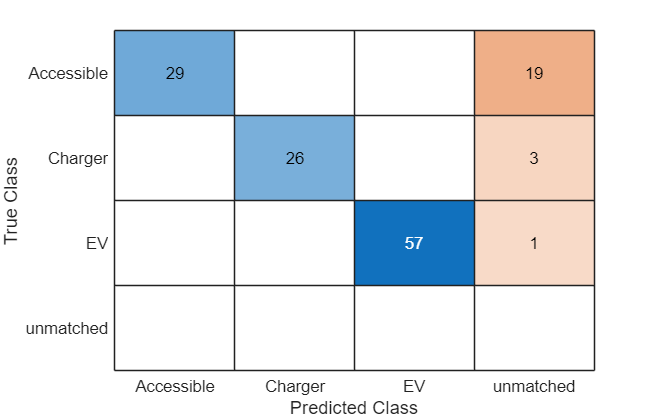

[cm, confusionClasses] = confusionMatrix(metrics);
confusionchart(cm{1}, confusionClasses)

## Choose a detection threshold

thresholds = 0.1:0.1:0.9;
mAPs = zeros(length(thresholds),1);
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(evYoloDetector, testData, "Threshold", thresholds(ii));
    currentMetrics = evaluateObjectDetection(results, testData, iou);
    datasetSummary = summarize(currentMetrics);
    mAPs(ii) = datasetSummary{:, "mAP0.5"};
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

## Visualize mAP vs detection threshold curve

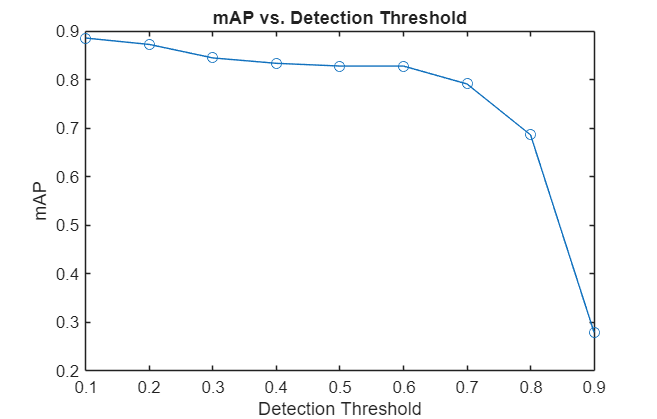

plot(thresholds, mAPs, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")